clear

(a) v=20km/h=72m/s, fc=2GHz

fprintf('(a) v=20km/h, fc=2GHz')

(a) v=20km/h, fc=2GHz

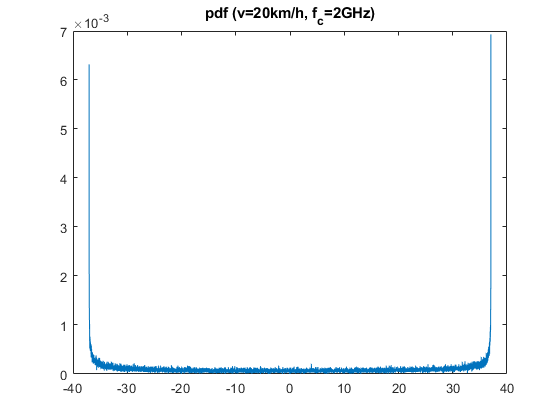

N=10^5; %number of samples
v=20;%(km/h)
f_c=2;%(GHz)
[counts,points]=plot_pdf(v,f_c,N);

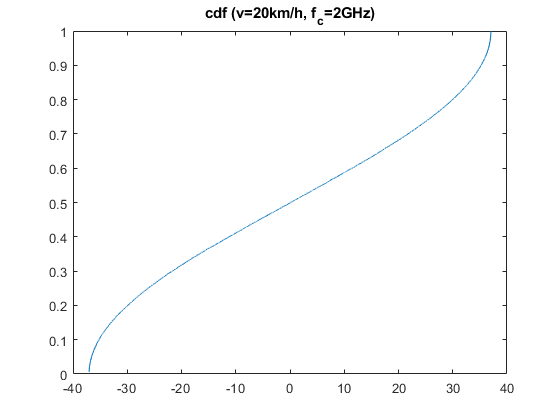

plot_cdf(counts,points,v,f_c)

(b) v=90km/h=324m/s, fc=26GHz

fprintf('(b) v=90km/h, fc=26GHz')

(b) v=90km/h, fc=26GHz

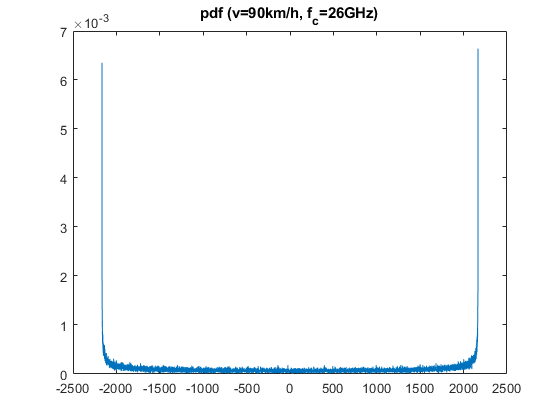

N=10^5;
v=90;
f_c=26;
[counts,points]=plot_pdf(v,f_c,N);

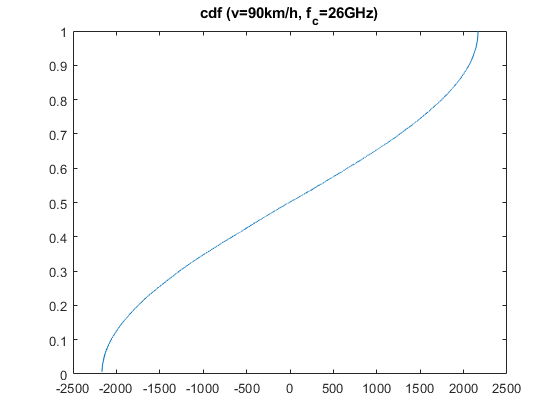

plot_cdf(counts,points,v,f_c)

(c) v ∼ U(20, 90)km/h=U(72, 324)m/s, fc=2GHz

fprintf('(c) V ∼ U(20, 90)km/h, fc=2GHz')

(c) V ∼ U(20, 90)km/h, fc=2GHz

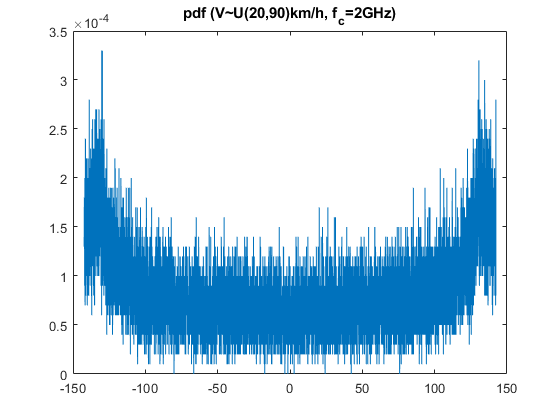

N=10^5;
v=20*rand(1,N)+70;
f_c=2;
[counts,points]=plot_pdf(v,f_c,N);

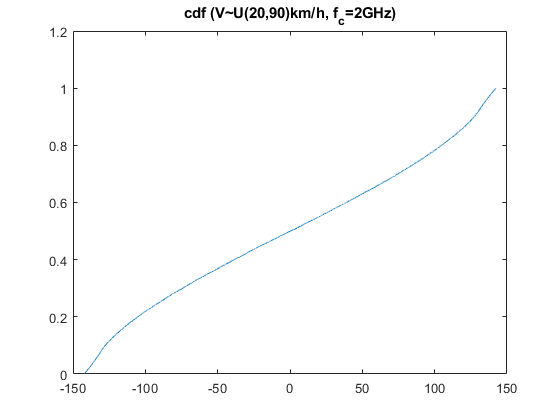

plot_cdf(counts,points,v,f_c)

(d)

fprintf('(d) compare theoretical result with simulation of (a)')

(d) compare theoretical result with simulation of (a)

N=10^5; %number of samples
v=20;%(km/h)
f_c=2;%(GHz)
c=3*10^8;
f_m=(v*1000/3600)*(f_c*10^9)/c;
F_Y=@(y) acos(-y/f_m)./pi;
f_Y=@(y) 1./(pi*f_m*sqrt(1-(y/f_m).^2));
y=[-f_m:2*f_m/10000:f_m];
y(end-4:end)=[];
y(1:5)=[];
[counts,points]=plot_pdf(v,f_c,N);
hold

Current plot held


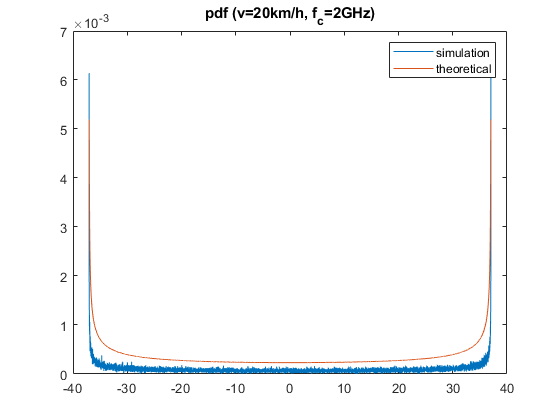

plot(y,f_Y(y)/f_m)
legend('simulation','theoretical')

plot_cdf(counts,points,v,f_c)
hold

Current plot held


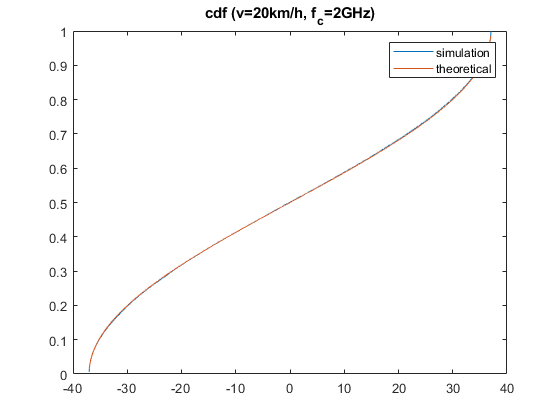

plot(y,F_Y(y))
legend('simulation','theoretical')